# PLATE Reader Operator pipeline

## Step 1: data loading and preparation

Add PLATERO set of functions to your working directory:

my = version('-release');
if str2double(my(1:4))<2020
    addpath(genpath('rprev2020'))
else
    addpath(genpath('r2020'))
end

Now, load the data resulting from the calibration experiment. In this case, we are reading the data from the file  "`Fluorescein_random_2020_rows_8rep_one_rep_per_sheet.xls`x". This data is organized by sheets, where each sheet has one repetition of the measurements. 

filename = "Fluorescein_random_2020_rows_8rep_one_rep_per_sheet.xlsx";
colnames = {'WellID','Well','Concentration','G50','G60','G70','G80','OD'};
dataPR = readexperiment(filename,"B102:I197",50:10:80,false,colnames);
size(dataPR)

ans =         3072           6


After loading all the sheets of the excel file, measurements are concatenated, grouping all in a single table variable and identifying them by their values for variables "Well","Gain" and "Repeat" (automatically generated by the function tableprep.m). The resulting table, dataPR (dataPlateReader), has the desired structure. 

Then, observations belonging to empty wells (used to measure the *F_BLK* term) and to wells with the reporter (Fluorescein in this case), are splitted in two different tables.

datPRblk = dataPR(isnan(dataPR{:,"Concentration"}),:);
datPRgfp = dataPR(~isnan(dataPR{:,"Concentration"}),:);
disp(strcat("This data set has ", string(size(datPRblk,1)),...
    " BLK observations and ", string(size(datPRgfp,1)), ...
    " GFP observations."))

This data set has 512 BLK observations and 2560 GFP observations.


Now, the gfp values are splitted in the training and validation data subsets:

rng(0207)
[datagfp_cal, datagfp_val] = cvsplit(datPRgfp, 0.7);
disp(strcat("The calibration data set has ", string(size(datagfp_cal,1)),...
    " observations and the validation data set has ", ...
    string(size(datagfp_val,1)), " observations."))

The calibration data set has 1760 observations and the validation data set has 800 observations.


the **calibration** data set has ***11 wells * 8 repetitions * 4 gains * 5 concentration levels  = 1760 observations***. Analagously, the **validation** data set has ***5 wells * 8 repetitions * 4 gains * 5 concentration levels = 800 observations***. 

These two sets are stored as different `.mat` files. Since the *F_BLK *term is estimated as well as a model parameter, the values in `blk_data` (n = 512) are added to the `data_cal` table.

data_cal = [datPRblk; datagfp_cal];
save('calibration.mat',"data_cal")
save('validation.mat',"datagfp_val")

## Step 2: Model fitting

load calibration.mat

Before fitting any expression to model the gain effect on the fluorescence values, it is crucial to assess the existence of missing data. This is quite often when different concentration levels are being used. 

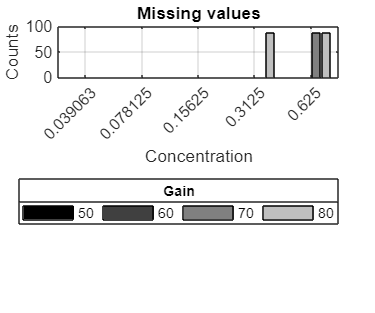

studmissing(data_cal)   

As it can be seen, there are missing values at some gains for the two maximum concentration levels. **For these reasons only the concentrations 0.0391, 0.0781 and 0.1562 will be used for the calibration purpose.** Thus, the resulting data set has ***11 wells * 8 repetitions * 4 gains * 3 concentration levels = 1056 observations***. 

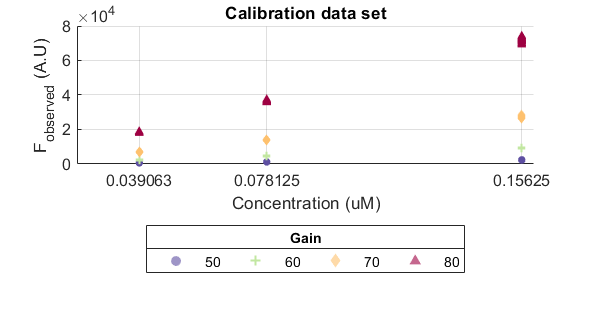

blk_data = data_cal(isnan(data_cal.Concentration),:);
flu_data = data_cal(~isnan(data_cal.Concentration),:);
flu_data(flu_data.Concentration > 0.3,:) = [];
figure('Position',[360 439 472 258]),
plotbyfactor(flu_data.Concentration,flu_data.Fobs,flu_data.Gain,1,0,...
    0,'Concentration (uM)','F_{observed} (A.U)',"Gain",'Calibration data set')

Once we stablished the range of values that will be used for the calibration, we proceed to estimate the *F_BLK* term. Before doing this, it is a good practice to check for potential outliers. As it can be seen in the figure below, one of the wells without Fluorescein (G6), has extreme values of fluorescence at gains 70 and 80.

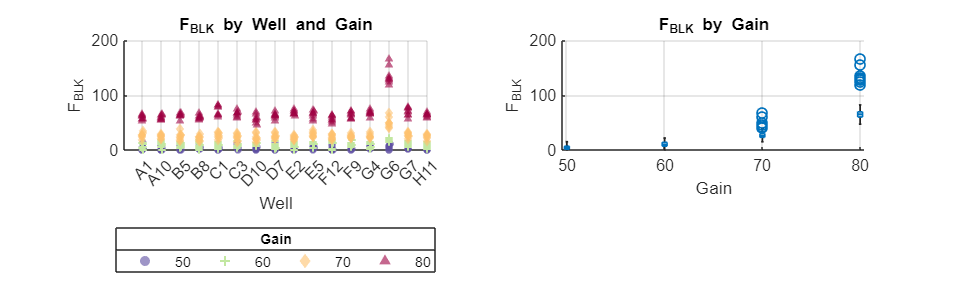

figure('Position',[360 456 770 241])
tiledlayout(1,2), nexttile
plotbyfactor(blk_data.Well,blk_data.Fobs,blk_data.Gain,1,0,0.001,...
    'Well','F_{BLK}',"Gain", 'F_{BLK} by Well and Gain')
xtickangle(45)
nexttile
boxchart(blk_data.Gain,blk_data.Fobs),grid on, xlabel('Gain'), 
ylabel('F_{BLK}'), title('F_{BLK} by Gain')

In order to prevent the influence of these outliers, we will estimate the $F_{\textrm{BLK}}$ term for each gain level ($F_{\textrm{BLK},G}$) by using the median. Another common option would be to use the average value to estimate $F_{\textrm{BLK},G}$. However, the breakdown point of the mean is really low, impliying that the presence of a single outlier could make its value not reliable anymore. The median presents a more robust behaviour and it is still a well-known and widely used robust location parameter. 

### Gain effect function ($f_G$) 

The first function to fit is the gain effect funtion, which represents how the gain parameter affects the fluorescence measurements. After fitting this relation, we will be able to remove this effect from the observed fluorescence values ($F_{\textrm{observed}}$):


$$F_{\textrm{reporter}} =\left(F_{\textrm{observed}} -F_{\textrm{BLK},G} \right)\exp \left(b_1 G+b_2 G^2 \right)$$


The function fitfg.m returns the estimated parameters $b_1$ and $b_2$from the previous equation. Moreover, it also returns the output of the ANOVA test on both coefficients for all levels of the concentration. As it can be seen, there are no statistically significant differences between the estimated values for different concentrations. As a result, this validates the assumption that the gain effect is the same for all concentrations being measured by the plate reader. 

ANOVA on coefficient b_1 for all levels of concentration


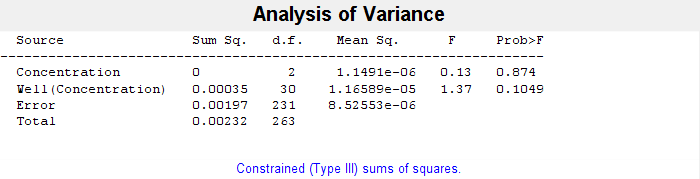

ANOVA on coefficient b_2 for all levels of concentration


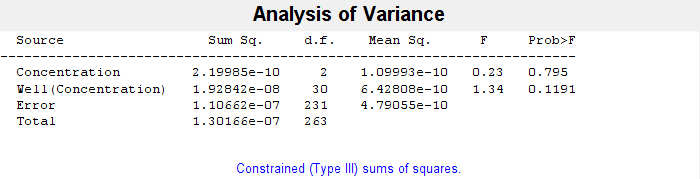

[model_parameters, flu_data, gmdata, fgtest] = fitfg(blk_data, flu_data);

After fitting the gain effect model, the gaincorrect.m function can be used to obtain the corrected fluorescence value for each well of the plate. The following figure represents the relationship between the $F_{\textrm{reporter}}$ (i.e., fluorescence without the gain and medium effect) and the true concentration for each observation in the flu_data table.

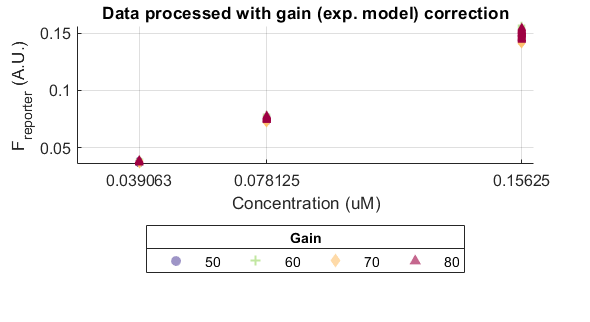

flu_data.Fcorr = gaincorrect(flu_data.Fobs, flu_data.Fblk, flu_data.Gain, ...
    model_parameters.b1, model_parameters.b2);
figure('Position',[360 439 472 258]),
plotbyfactor(flu_data.Concentration,flu_data.Fcorr,flu_data.Gain,1,0,0, ...
    'Concentration (uM)','F_{reporter} (A.U.)','Gain', ...
    'Data processed with gain (exp. model) correction'), legend

### Units Conversion function ($f_{\textrm{UC}}$)

Using the true concentration and the corrected fluorescence, we can input them to the fitfc.m function to estimate the coefficients of the units conversion model: $C=c_0 +c_1 F_{\textrm{reporter}}$

[c_CF, CFmodel] = fitfuc(flu_data.Fcorr,flu_data.Concentration);
model_parameters.c0 = c_CF{1,1};
model_parameters.c1 = c_CF{2,1};
flu_data.CPred = flu2conc(flu_data.Fcorr, model_parameters.c0, ...
    model_parameters.c1);

The resulting model is shown in the following figure:

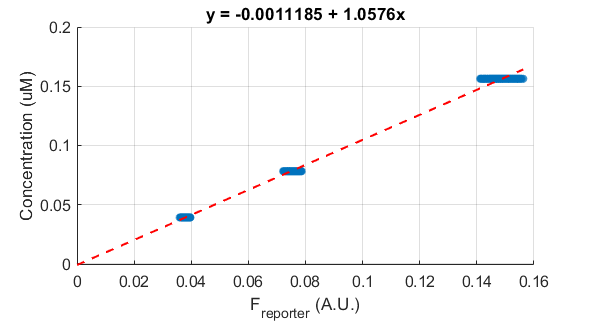

figure('Position',[360 439 472 258]),
plotcalib(flu_data.Fcorr,flu_data.Concentration, model_parameters.c0, ...
    model_parameters.c1);

### Quantify uncertainty in the predictions

In order to provide an estimate of the uncertainty expected in the predictions, we must check the error or bias of the predictions. In this case, there seems to be a clear heterocedasticity on the residuals. This is indicating a proportional effect of the concentration on the variability of the error values. As it can be seen in the following figure, this can be easily neutralised by scaling the error with the concentration. Thus, the final $s_{\textrm{Bias}}$ estimate is calculated as the standard deviation of the scaled bias (sBiasnorm). 

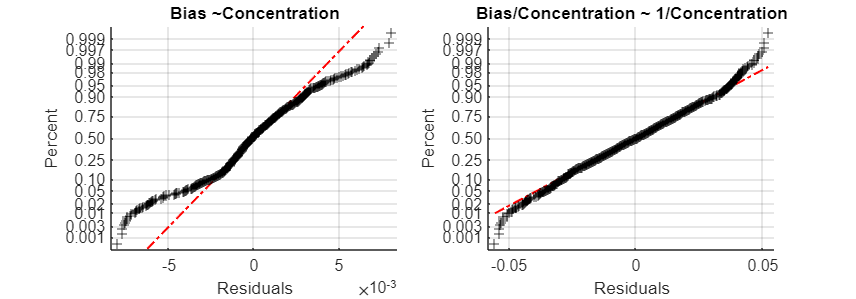

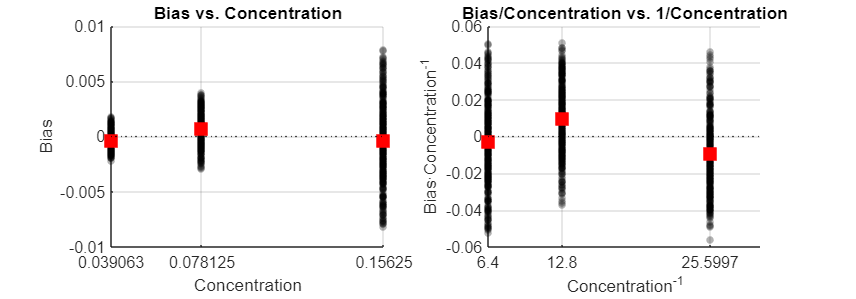

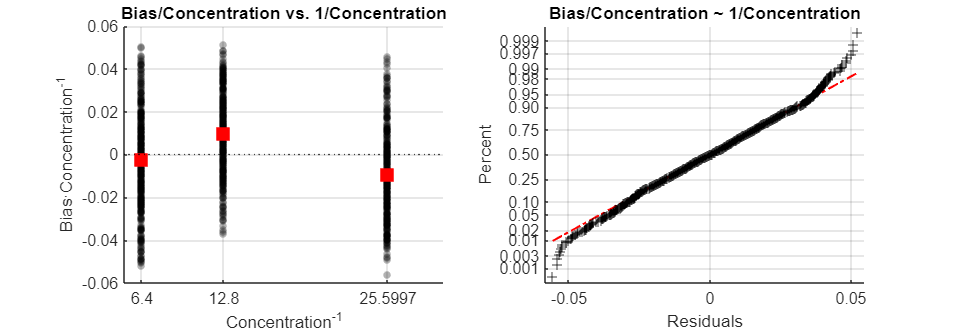

sBias = 0.0024

sBiasnorm = 0.0225

mdlBias = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat     pValue 
                   __________    __________    _______    _______

    (Intercept)    0.00021784    0.00015544     1.4014    0.16138
    x1               -0.00239      0.001504    -1.5891    0.11235


Number of observations: 1056, Error degrees of freedom: 1054
Root Mean Squared Error: 0.00238
R-squared: 0.00239,  Adjusted R-Squared: 0.00144
F-statistic vs. constant model: 2.53, p-value = 0.112

mdlBiasnorm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)      0.0070299     0.0014425     4.8732    1.2663e-06
    x1             -0.00051809    8.5193e-05    -6.0814    1.6642e-09


Number of observations: 1056, Error degrees of freedom: 1054
Root Mean Squared Error: 0.0221
R-squared: 0.0339,  Adjusted R-Squared: 0.033
F-statistic vs. constant model: 37, p-value = 1.66e-09

figure('Position',[360 458 685 239])
[sBias, sBiasnorm, mdlBias, mdlBiasnorm] = quantifyuncertainty( ...
    flu_data.Concentration, flu_data.CPred, "Concentration")

model_parameters.sBias = sBiasnorm;
model_parameters.EDF = mdlBiasnorm.DFE;
disp(model_parameters)

    F_BLK (G = 50)    F_BLK (G = 60)    F_BLK (G = 70)    F_BLK (G = 80)      b1           b2            c0          c1       sBias      EDF 
    ______________    ______________    ______________    ______________    _______    __________    __________    ______    ________    ____

          4                 10                26                65          0.24298    -0.0009933    -0.0011185    1.0576    0.022472    1054



calmetrics.mse = mean((flu_data.Concentration - flu_data.CPred).^2);
calmetrics.relerr = abs(flu_data.Concentration - ...
    flu_data.CPred)./flu_data.Concentration;
calmetrics.minrelerror = min(calmetrics.relerr);
calmetrics.maxrelerror = max(calmetrics.relerr);
save('cal_results.mat', 'calmetrics', 'model_parameters')
save('coefficients.mat', 'model_parameters')

## Step 3: Model Validation

Now, the coefficients obtained in the model fitting step (shown in the previous table), are used to predict the concentration values from the observed fluorescence values that were not used to fit the model. 

### Prediction inside the training concentration range

In this case, the prediction data set contains the recorded fluorescence values for concentrations within the same range of the model calibration step. 

clearvars
load validation.mat
load coefficients.mat
flu_data = datagfp_val(datagfp_val.Concentration<0.3,:);
G = unique(flu_data.Gain);
% Assign the correspoding F_BLK values to each observation F_obs
flu_data.Fblk = repmat(model_parameters{:,["F_BLK (G = 50)", "F_BLK (G = 60)",...
   "F_BLK (G = 70)", "F_BLK (G = 80)"]}',...
    size(flu_data,1)/length(G),1);

First, the gain effect is corrected:

flu_data.Fcorr = gaincorrect(flu_data.Fobs, flu_data.Fblk, flu_data.Gain, ...
    model_parameters.b1, model_parameters.b2);

Next, the corrected fluorescence values are converted to concentration values:

flu_data.CPred = flu2conc(flu_data.Fcorr, model_parameters.c0, ...
    model_parameters.c1);

The following scatterplot shows the predicted concentration values vs. the observed (true) concentrations. As it can be seen, there is a clear match between predictions and real values.

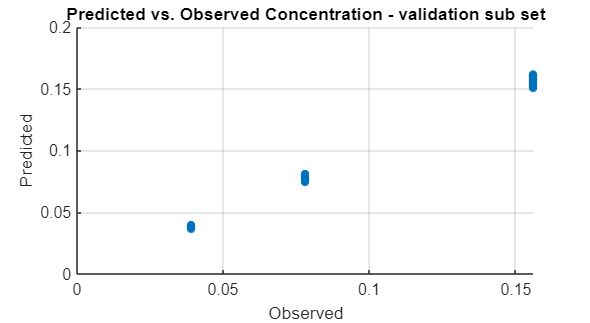

figure('Position', [360 439 472 258]),
plotcalib(flu_data.Concentration,flu_data.CPred,nan,nan);
hold on
plot(0,0,'MarkerFaceColor','none', 'MarkerEdgeColor','none')
xlabel('Observed'),ylabel('Predicted')
title('Predicted vs. Observed Concentration - validation sub set')

Next, the MSA is performed on the validation data set. First, the R&R analysis is carried out. For all concentration levels, the variability introduced by the measurement system is less than the "Part-to-Part" variability. This indicates a high repeatability and reproducibility of the measurement system.

R & R Analysis on measurements for C = 0.039063


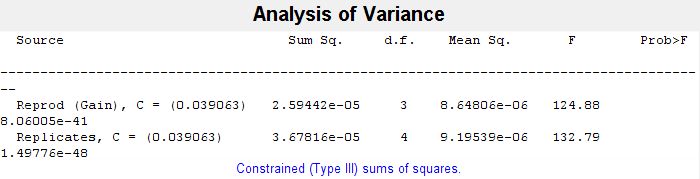

R & R Analysis on measurements for C = 0.078125


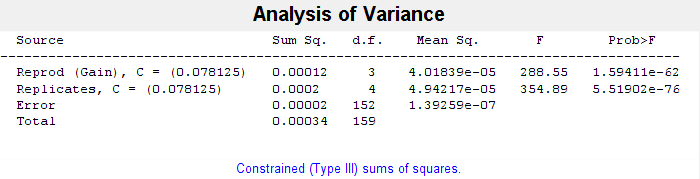

R & R Analysis on measurements for C = 0.15625


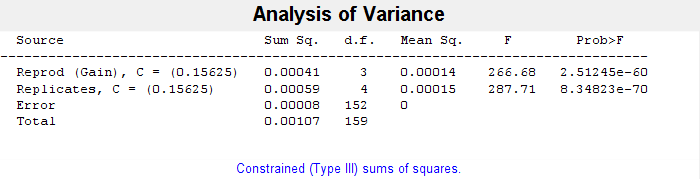

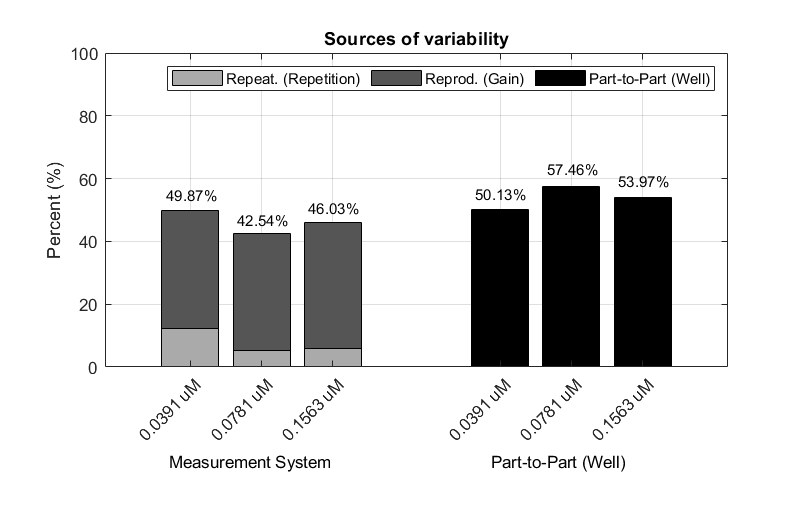

%% RR
[~, vprocv] = randr(flu_data.CPred,flu_data.Well,flu_data.Concentration,...
    flu_data.Gain,flu_data.Repeat,1);

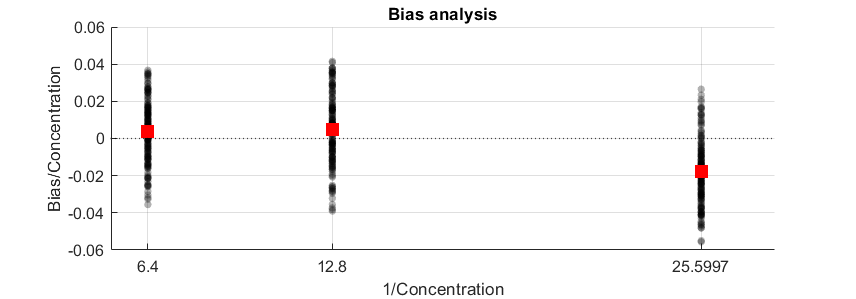

figure('Position',[360 458 685 239])
[mdl, lin_comp, bias_comp] = biasanalysis(flu_data.Concentration, ...
    flu_data.CPred,vprocv,1,1,"1/Concentration");

disp(mdl)

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)      0.015218     0.0017414     8.7389    4.0025e-17
    x1             -0.0012234    0.00010284    -11.896    9.1553e-29


Number of observations: 480, Error degrees of freedom: 478
Root Mean Squared Error: 0.018
R-squared: 0.228,  Adjusted R-Squared: 0.227
F-statistic vs. constant model: 142, p-value = 9.16e-29


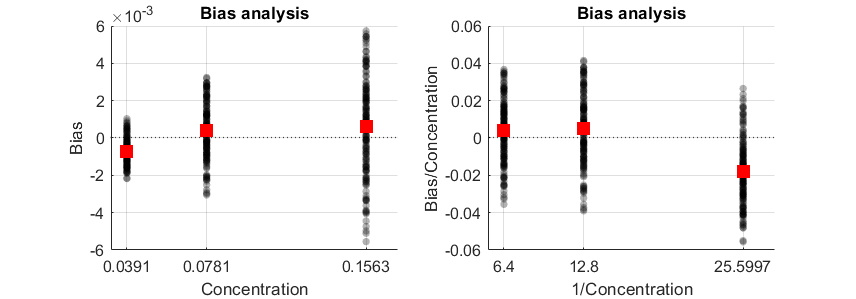

figure('Position',[360 458 685 239])
subplot(121)
mdl_nots = biasanalysis(flu_data.Concentration,flu_data.CPred,vprocv,...
    0,0,"Concentration");
subplot(122)
mdl_sc = biasanalysis(flu_data.Concentration,flu_data.CPred,vprocv,...
    1,1,"1/Concentration");

Finally, using the estimates for the concentration and for the expected uncertainty, Confidence Intervals for the true concentration values, are obtained. 

[LowCI, UpCI] = cipred(flu_data.CPred, model_parameters.sBias, ...
    model_parameters.EDF);
[Percent_in_calrange] = validateci(LowCI, UpCI, flu_data.Concentration);

#### Error metrics

The following metrics express the accuracy of the units conversion procedure, evaluated with the validation data set:

valmetrics_inrange.pctgeci = Percent_in_calrange;
valmetrics_inrange.mse = mean((flu_data.Concentration - flu_data.CPred).^2);
valmetrics_inrange.relerr = abs(flu_data.Concentration - ...
    flu_data.CPred)./flu_data.Concentration;
valmetrics_inrange.minrelerror = min(valmetrics_inrange.relerr);
valmetrics_inrange.maxrelerror = max(valmetrics_inrange.relerr);
disp(valmetrics_inrange)

        pctgeci: 97.9167
            mse: 3.4285e-06
         relerr: [480×1 double]
    minrelerror: 1.7022e-05
    maxrelerror: 0.0556



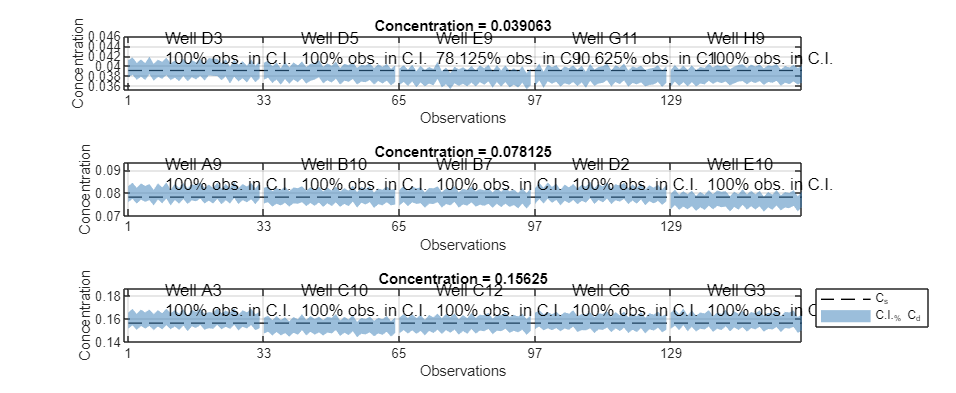

figure('Position',[111 276 1027 421]),
ciplots(flu_data, model_parameters.sBias, model_parameters.EDF,linspecer(1))

As it can be seen in the previous figure, some wells show confidence intervals (shaded area) systematically above or below the true concentration value (dashed line). In the following plots, the raw fluorescence values are displayed, showing that the same bias seen in the predictions can be observed as well in the measurements. This suggests that the bias in the aforementioned predictions is a consequence of the variability in the experimental procedure, and not a result of a model inadequacy.

Observed fluorescence for concentration = 0.039063


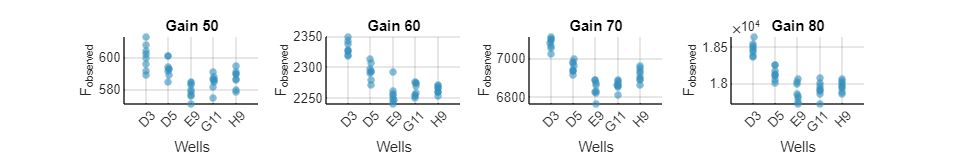

Observed fluorescence for concentration = 0.078125


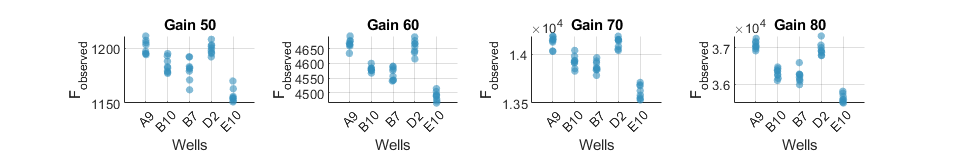

Observed fluorescence for concentration = 0.15625


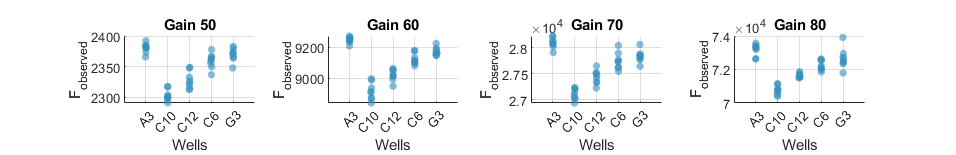

uconc = unique(flu_data.Concentration);
ug = unique(flu_data.Gain);
for uc = 1:length(uconc)
    figure('Name',strcat('Concentration = ', string(uconc(uc))),'Position',...
        [29 552 891 145]),
    disp(strcat("Observed fluorescence for concentration = ", string(uconc(uc))))
    tiledlayout(1,length(ug)),
    flu_conc = flu_data(flu_data.Concentration==uconc(uc),:);
    for iu = 1:length(ug)
        nexttile,
        plotbyfactor(flu_conc.Well(flu_conc.Gain == ug(iu)), ...
            flu_conc.Fobs(flu_conc.Gain == ug(iu)), ...
            flu_conc.Gain(flu_conc.Gain == ug(iu)),1,0,0.01)
        title(strcat("Gain ", string(ug(iu)))), 
        xlabel('Wells'), ylabel('F_{observed}')
        legend('off')
    end
end

load cal_results.mat
perftable = table([calmetrics.mse;valmetrics_inrange.mse],...
    [calmetrics.minrelerror;valmetrics_inrange.minrelerror]*100,...
    [calmetrics.maxrelerror;valmetrics_inrange.maxrelerror]*100,...
    'RowNames',{'Calibration', 'Validation (within range)'},...
    'VariableNames',{'MSE','Min.Rel.Error (%)','Max.Rel.Error (%)'});
display(perftable)

perftable = 2×3 table
                                    MSE        Min.Rel.Error (%)    Max.Rel.Error (%)
                                 __________    _________________    _________________

    Calibration                  5.6728e-06         0.004034             5.6197      
    Validation (within range)    3.4285e-06        0.0017022             5.5619      


### Prediction outside the training concentration range

In this second validation scenario, we address the question: Is the fitted model able to extrapolate? To answer it, we exploit the model from the calibration step with data of two concentration levels that were not used in the model building. 

% Load the data
blk_data = datagfp_val(isnan(datagfp_val.Concentration),:);
flu_data = datagfp_val(and(~isnan(datagfp_val.Concentration), ...
    datagfp_val.Concentration > 0.16),:);
% Some arrangements
G = unique(flu_data.Gain);
flu_data.Fblk = repmat(model_parameters{:,["F_BLK (G = 50)", "F_BLK (G = 60)",...
   "F_BLK (G = 70)", "F_BLK (G = 80)"]}',...
    size(flu_data,1)/length(G),1);
% Check missings:
flu_data = flu_data(~isnan(flu_data.Fobs),:);
% Gain effect correction 
flu_data.Fcorr = gaincorrect(flu_data.Fobs, flu_data.Fblk, flu_data.Gain, ...
    model_parameters.b1, model_parameters.b2);
% Conversion to concentration
flu_data.CPred = flu2conc(flu_data.Fcorr, model_parameters.c0, ...
    model_parameters.c1);

The results after the units conversion is displayed in the following scatterplot:

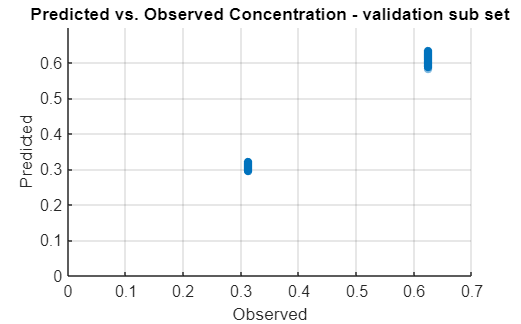

figure('Position',[503 438 417 259])
plotcalib(flu_data.Concentration,flu_data.CPred,nan,nan);
hold on
plot(0,0,'MarkerFaceColor','none', 'MarkerEdgeColor','none')
xlabel('Observed'),ylabel('Predicted')
title('Predicted vs. Observed Concentration - validation sub set')

Like with the previous validation, in this case we also study the performance of the measurement system by running an R&R and L&B analyses on the data with these two higher concentrations.

R & R Analysis on measurements for C = 0.3125


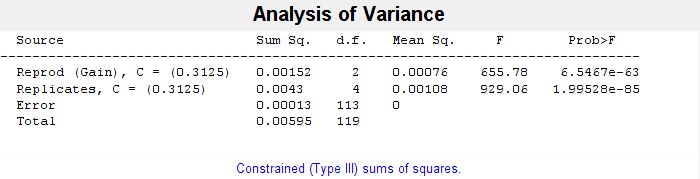

R & R Analysis on measurements for C = 0.625


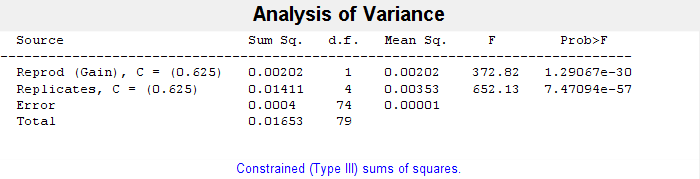

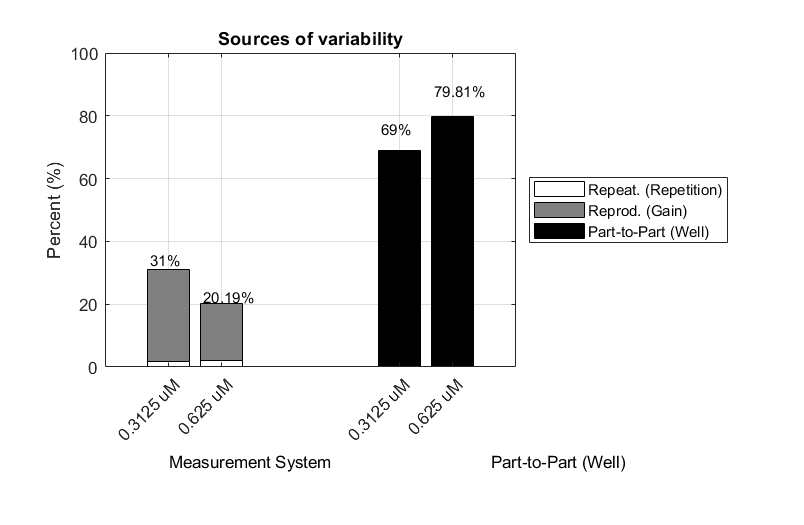

%% RR
[s_RandR, vprocv] = randr(flu_data.CPred,flu_data.Well,flu_data.Concentration, ...
    flu_data.Gain,flu_data.Repeat,1);

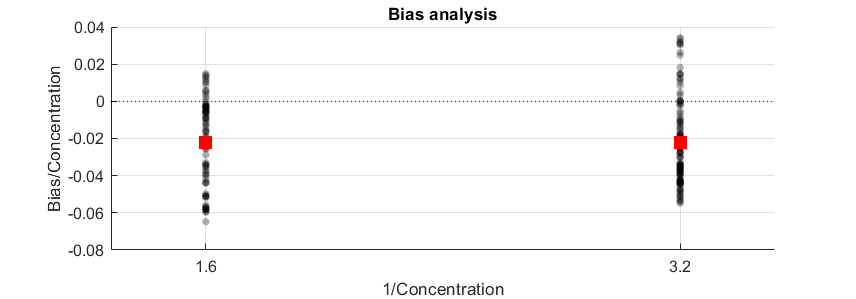

figure('Position',[360 458 685 239])
[mdl, lin, bias] = biasanalysis(flu_data.Concentration,flu_data.CPred, ...
    vprocv,1, 0,"1/Concentration");

In this case, the contribution of the "Part-to-Part" variability is increased. Consequently, the contribution to the total variability by the measurement system, is reduced, resulting in a better repeatability and reproducibility than in previous analyses. 

[LowCI, UpCI] = cipred(flu_data.CPred, model_parameters.sBias, ...
    model_parameters.EDF);
[Percent_in_outrange] = validateci(LowCI, UpCI, flu_data.Concentration);

#### Error metrics

The following metrics summarize the performance of the model to predict concentration values outside the calibration range. As it can be seen, the percentage of confidence intervals containind the true concentration value decreases. However, when the raw fluorescence measurements are visualized, it can be seen that the same bias from the confidence intervals, can be appreciated on the measurements. This, as in the previous case, suggests that the errors in the predictions are a consequence of the experimental variability.

valmetrics_outrange.pctgeci = Percent_in_outrange;
valmetrics_outrange.mse = mean((flu_data.Concentration - flu_data.CPred).^2);
valmetrics_outrange.relerr = abs(flu_data.Concentration - ...
    flu_data.CPred)./flu_data.Concentration;
valmetrics_outrange.minrelerror = min(valmetrics_outrange.relerr);
valmetrics_outrange.maxrelerror = max(valmetrics_outrange.relerr);
disp(valmetrics_outrange)

        pctgeci: 76.5000
            mse: 2.1788e-04
         relerr: [200×1 double]
    minrelerror: 4.0943e-05
    maxrelerror: 0.0647



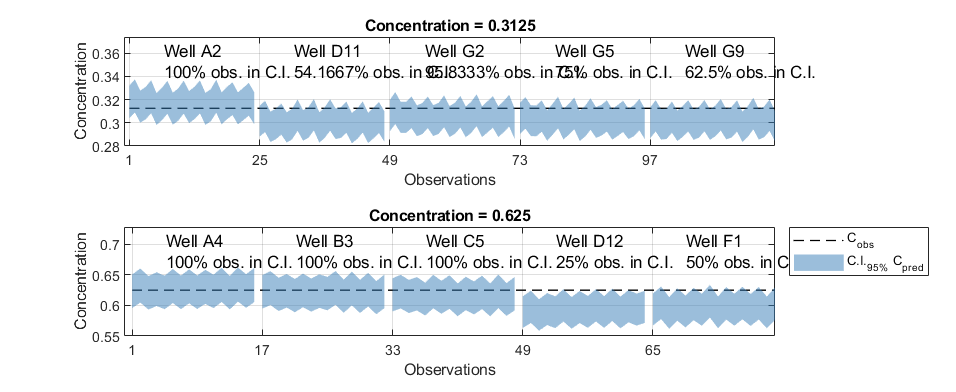

%%
figure('Position',[111 276 1027 421]),
ciplots(flu_data, model_parameters.sBias, model_parameters.EDF,linspecer(1))

Observed fluorescence for concentration = 0.3125


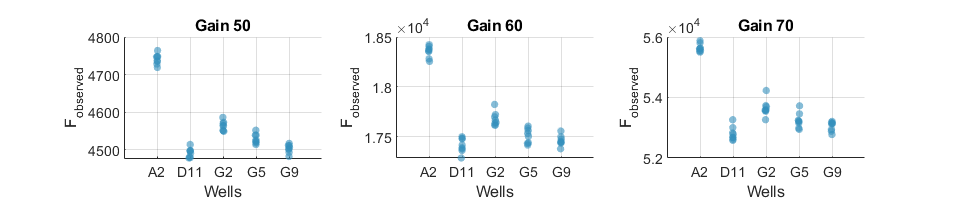

Observed fluorescence for concentration = 0.625


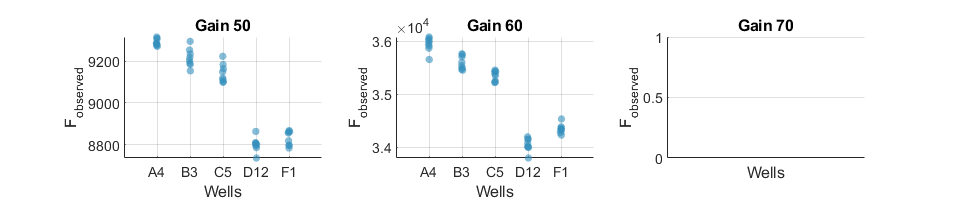

uconc = unique(flu_data.Concentration);
ug = unique(flu_data.Gain);
for uc = 1:length(uconc)
    figure('Name',strcat('Concentration = ', string(uconc(uc))),...
        'Position',[29 498 891 199]),
    disp(strcat("Observed fluorescence for concentration = ", string(uconc(uc))))
    tiledlayout(1,length(ug)),
    flu_conc = flu_data(flu_data.Concentration==uconc(uc),:);
    for iu = 1:length(ug)
        nexttile,
        plotbyfactor(flu_conc.Well(flu_conc.Gain == ug(iu)), ...
            flu_conc.Fobs(flu_conc.Gain == ug(iu)), ...
            flu_conc.Gain(flu_conc.Gain == ug(iu)),1,0,0.01)
        title(strcat("Gain ", string(ug(iu)))), xlabel('Wells'), ylabel('F_{observed}')
        legend('off')
    end
end

load cal_results.mat
perftable = table([calmetrics.mse;valmetrics_outrange.mse],...
    [calmetrics.minrelerror;valmetrics_outrange.minrelerror]*100,...
    [calmetrics.maxrelerror;valmetrics_outrange.maxrelerror]*100,...
    'RowNames',{'Calibration', 'Validation (outside range)'},...
    'VariableNames',{'MSE','Min.Rel.Error (%)','Max.Rel.Error (%)'});
display(perftable)

perftable = 2×3 table
                                     MSE        Min.Rel.Error (%)    Max.Rel.Error (%)
                                  __________    _________________    _________________

    Calibration                   5.6728e-06         0.004034             5.6197      
    Validation (outside range)    0.00021788        0.0040943             6.4732      


### Using other $f_G$ function

In this last example we will use a different expression to model the gain effect on the plate reader measurements. The expression will be: $\left.{\left(F\right.}_{\textrm{obs}} -F_{\textrm{BLK},G} \right)/G$.

This model has some common points with our proposal, such as the additive effect of the medium, expressed by the $F_{\textrm{BLK}}$ term. However, the previous expression assumes a linear gain effect, i.e., the observed fluorescence is proportional to the gain used for its acquisition. 

As we did before, we will fit the model with the calibration data set and then validate the results with the validation data set. Nonetheless, given the results seen in the normal probability plots one could be suspicious enough about the model lack of fit, without necessarily carrying out the validation step.

load calibration.mat
model_parameters2 = model_parameters;
flu_data2 = data_cal(~isnan(data_cal.Concentration),:);
flu_data2(flu_data2.Concentration > 0.3,:) = [];
G = unique(flu_data2.Gain);
flu_data2.Fblk = repmat(model_parameters2{:,["F_BLK (G = 50)", ...
    "F_BLK (G = 60)","F_BLK (G = 70)", "F_BLK (G = 80)"]}',...
    size(flu_data2,1)/length(G),1);
flu_data2.Fcorr = (flu_data2.Fobs - flu_data2.Fblk)./ flu_data2.Gain;

The following scatterplot, with the corrected values, shows that the gain effect is clearly persistent:

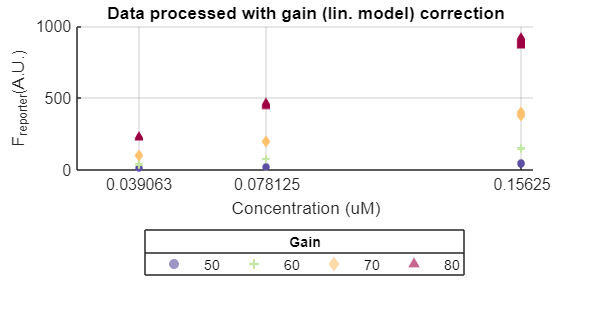

figure('Position',[360 439 472 258]),
plotbyfactor(flu_data2.Concentration,flu_data2.Fcorr,flu_data2.Gain,1,0,0, ...
    'Concentration (uM)','F_{reporter}(A.U.)','Gain',...
    'Data processed with gain (lin. model) correction')

[c_CF2, CFmodel2] = fitfuc(flu_data2.Fcorr,flu_data2.Concentration);
model_parameters2.c0 = c_CF2{1,1};
model_parameters2.c1 = c_CF2{2,1};

flu_data2.CPred = flu2conc(flu_data2.Fcorr, model_parameters2.c0, ...
    model_parameters2.c1);

Although the previous figure is clearly indicating the inadequacy of the $f_G$ function, further steps of the calibration procedure can serve as a proof of the goodness or badness of the model expression. As it can be seen in the  probability plots with the residuals of the bias model, there is a complete lack of normality. This suggests that some relevant information is still on the bias residuals, because it is not being properly captured by the units conversion model. 

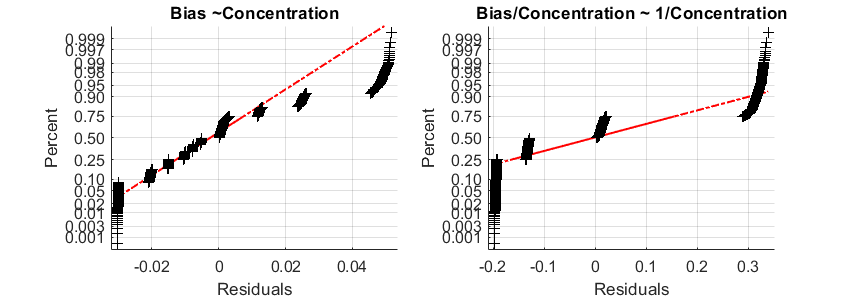

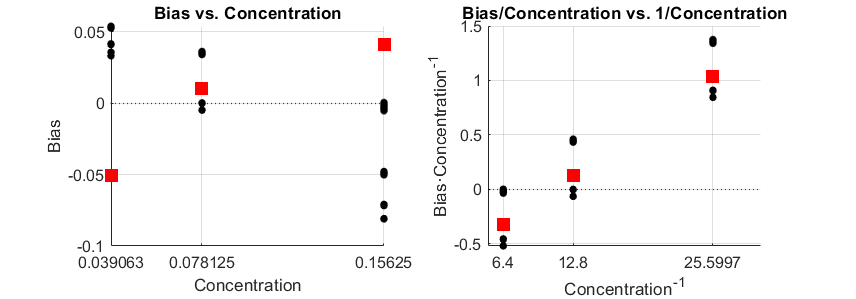

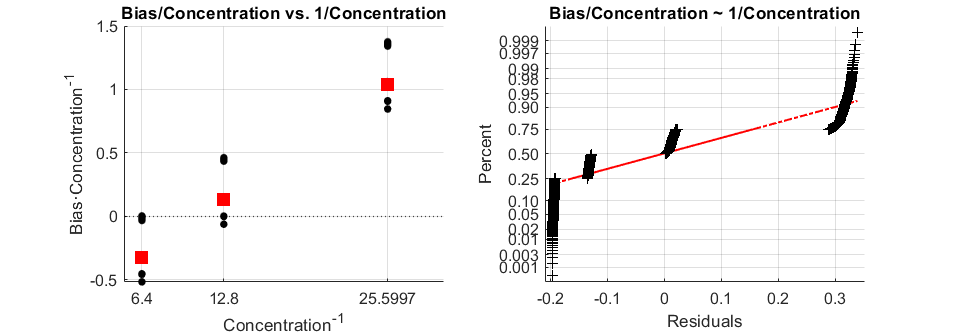

figure('Position',[360 458 685 239])
[sBias2, sBiasnorm2, mdl1fg2, mdl2fg2] = quantifyuncertainty( ...
    flu_data2.Concentration, flu_data2.CPred, "Concentration");

model_parameters2.sBias = sBiasnorm2;
model_parameters2.DFE = mdl2fg2.DFE;

#### Model validation via measurement system validation

As we mentioned before, the R&R and the B&L analyses are performed on the predicted concentration. Thus, when we are validating the measurement system, we are including the units conversion operation as part of the measurement. This implies that valid measurements are equivalent to valid $f_G$ and $f_C$functions. Otherwise, if the units conversion model is based on wrong $f_G$ and $f_C$expressions, it should stand out in the following analysis.

R & R Analysis on measurements for C = 0.039063


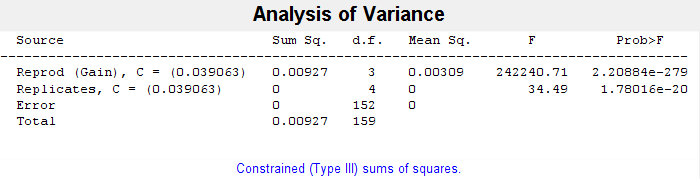

R & R Analysis on measurements for C = 0.078125


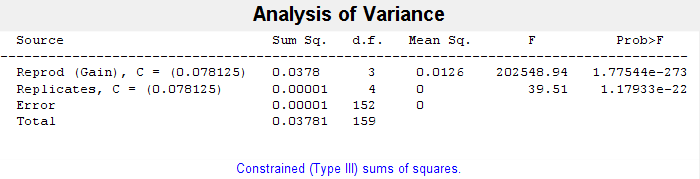

R & R Analysis on measurements for C = 0.15625


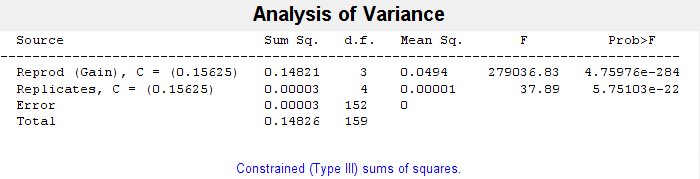

load validation.mat

flu_dataval2 = datagfp_val(datagfp_val.Concentration<0.3,:);
G = unique(flu_dataval2.Gain);
% Assign the correspoding F_BLK values to each observation F_obs
flu_dataval2.Fblk = repmat(model_parameters2{:,["F_BLK (G = 50)", "F_BLK (G = 60)",...
   "F_BLK (G = 70)", "F_BLK (G = 80)"]}',...
    size(flu_dataval2,1)/length(G),1);
flu_dataval2.Fcorr = (flu_dataval2.Fobs - flu_dataval2.Fblk)./ flu_dataval2.Gain;
flu_dataval2.CPred = flu2conc(flu_dataval2.Fcorr, model_parameters2.c0, ...
    model_parameters2.c1);

[s_RandR2, vproc2] = randr(flu_dataval2.CPred, flu_dataval2.Well, ...
    flu_dataval2.Concentration, flu_dataval2.Gain, flu_dataval2.Repeat,1);

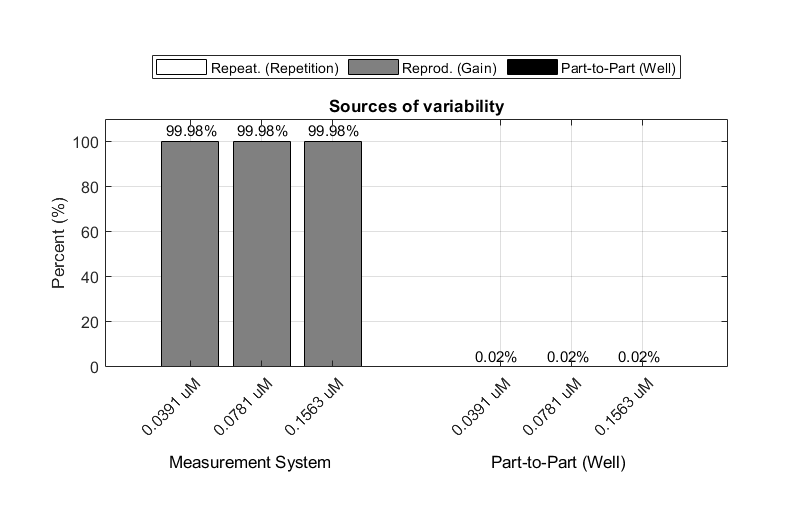

ylim([0,110])

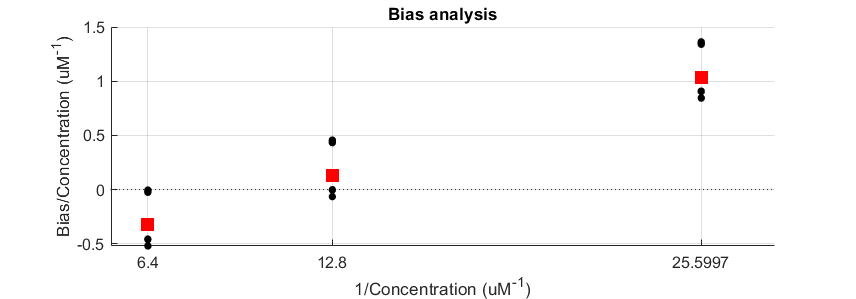

figure('Position',[360 458 685 239])
[mdl_scaled_2, lin2, bias2] = biasanalysis(flu_dataval2.Concentration, ...
    flu_dataval2.CPred, vproc2, 1, 0, "1/Concentration (uM^{-1})");

disp(mdl_scaled_2)

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)     -0.7783     0.018968    -41.033    9.6469e-159
    x1             0.070975    0.0011202      63.36      1.06e-234


Number of observations: 480, Error degrees of freedom: 478
Root Mean Squared Error: 0.196
R-squared: 0.894,  Adjusted R-Squared: 0.893
F-statistic vs. constant model: 4.01e+03, p-value = 1.06e-234


As it can be seen, the results displayed above clearly show that the units conversion model based on the linear gain effect, is not valid. This can be appreciated in the high contribution of the reproducibility term to the total variance of the measurementes, which is the factor causing nearly the 100% of the total variability among the observations. 

#### Error metrics

[LowCI, UpCI] = cipred(flu_dataval2.CPred, model_parameters2.sBias, ...
    model_parameters2.DFE);
[Percent_in_fg2] = validateci(LowCI, UpCI, flu_dataval2.Concentration);

valmetrics_fg2.pctgeci = Percent_in_fg2;
valmetrics_fg2.mse = mean((flu_dataval2.Concentration - flu_dataval2.CPred).^2);
valmetrics_fg2.relerr = abs(flu_dataval2.Concentration - ...
    flu_dataval2.CPred)./flu_dataval2.Concentration;
valmetrics_fg2.minrelerror = min(valmetrics_fg2.relerr);
valmetrics_fg2.maxrelerror = max(valmetrics_fg2.relerr);
disp(valmetrics_fg2)

        pctgeci: 100
            mse: 0.001849404179901
         relerr: [480×1 double]
    minrelerror: 3.764476747019075e-05
    maxrelerror: 1.366819364812086

